R = 5.7844

R = 5.7844

Rl = 297

Rl = 297

L = 0.44

L = 0.4400

Ke = 0.3914

Ke = 0.3914

W = tf([Rl/Ke/L 0], [1 (R+Rl)/L])

W =
 
   1725 s
  ---------
  s + 688.1
 
Continuous-time transfer function.



% syms p t
% Wp = ( Rl*Ke/L*p ) / (p+ (R+Rl)/L) 
% Wp = ( Rl*Ke/L ) / (p+ (R+Rl)/L)
% w = ilaplace(Wp)
% impulse(W)
% step(W)
% hold on
% grid on
% fplot(w,[0,0.014],"red")


% per =  Ke*Rl *(L * ( exp( -t *(Rl + R)/L ) - 1 ) + t*(Rl+R) ) / ((Rl+R)^2)
% fplot(per,[0,0.014],"red")

% h = (Ke* L* M exp(-(M* t) / (L - (R t)\/L)) / (M^2 + 2 M R + R^2) - (K L M)\/(M^2 + 2 M R + R^2) + (K M t)\/(M + R)
% syms s 
% b = Km/J/R
% a = Ke*Km/J/R
% teta = 1/Km - 1/Km*exp(-Km*Ke/J/R*t)
% pereh = t/Km+J*R/Km^2/Ke*exp(-Km*Ke/J/R*t)
% step(W)
% hold on
% grid on
% p = [1 Km*Ke/J/R 0]
% roots(p)
% fplot(per,[0,0.1],"red")
% 

% АЧХ
syms w

Wjw = ( Rl*Ke/L*1i*w ) / (1i*w+ (R+Rl)/L)

$$Wjw = \frac{52839\,w\,\mathrm{i}}{200\,\left(\frac{6052999427439627}{8796093022208}+w\,\mathrm{i}\right)}$$



A1=sqrt(real(Wjw)^2+imag(Wjw)^2)

$$A1 = \sqrt{{\mathrm{imag}\left(\frac{52839\,w\,\mathrm{i}}{200\,\left(\frac{6052999427439627}{8796093022208}+w\,\mathrm{i}\right)}\right)}^{2}+{\mathrm{real}\left(\frac{52839\,w\,\mathrm{i}}{200\,\left(\frac{6052999427439627}{8796093022208}+w\,\mathrm{i}\right)}\right)}^{2}}$$

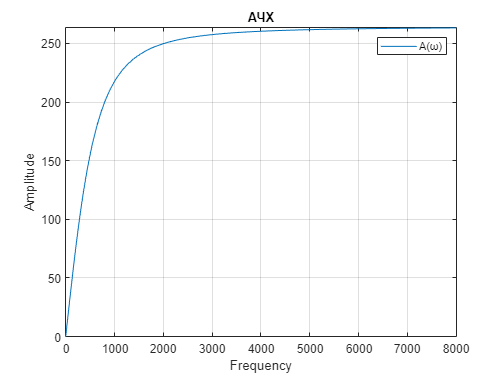


fplot(A1,[0,8000])
grid on
xlabel("Frequency")
ylabel("Amplitude")
title("АЧХ")
legend("A(ω)")

% фчх
F=atan2(imag(Wjw), real(Wjw))

$$F = \text{angle}\left(\mathrm{imag}\left(\frac{52839\,w\,\mathrm{i}}{200\,\left(\frac{6052999427439627}{8796093022208}+w\,\mathrm{i}\right)}\right)\,\mathrm{i}+\mathrm{real}\left(\frac{52839\,w\,\mathrm{i}}{200\,\left(\frac{6052999427439627}{8796093022208}+w\,\mathrm{i}\right)}\right)\right)$$

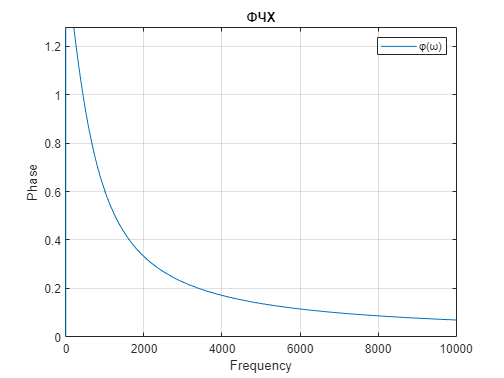


fplot(F,[0,10000])
grid on
xlabel("Frequency")
ylabel("Phase")
title("ФЧХ")
legend("φ(ω)")

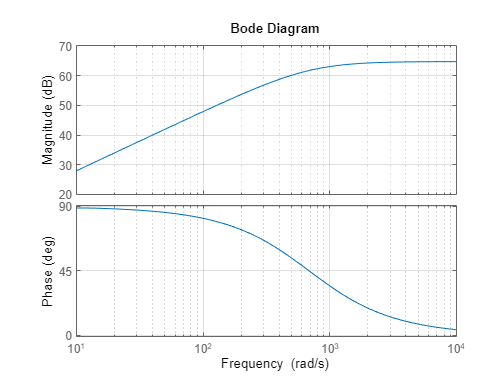



bode(W)
grid on